**GIVEN CONDITIONS - for each flight situation**

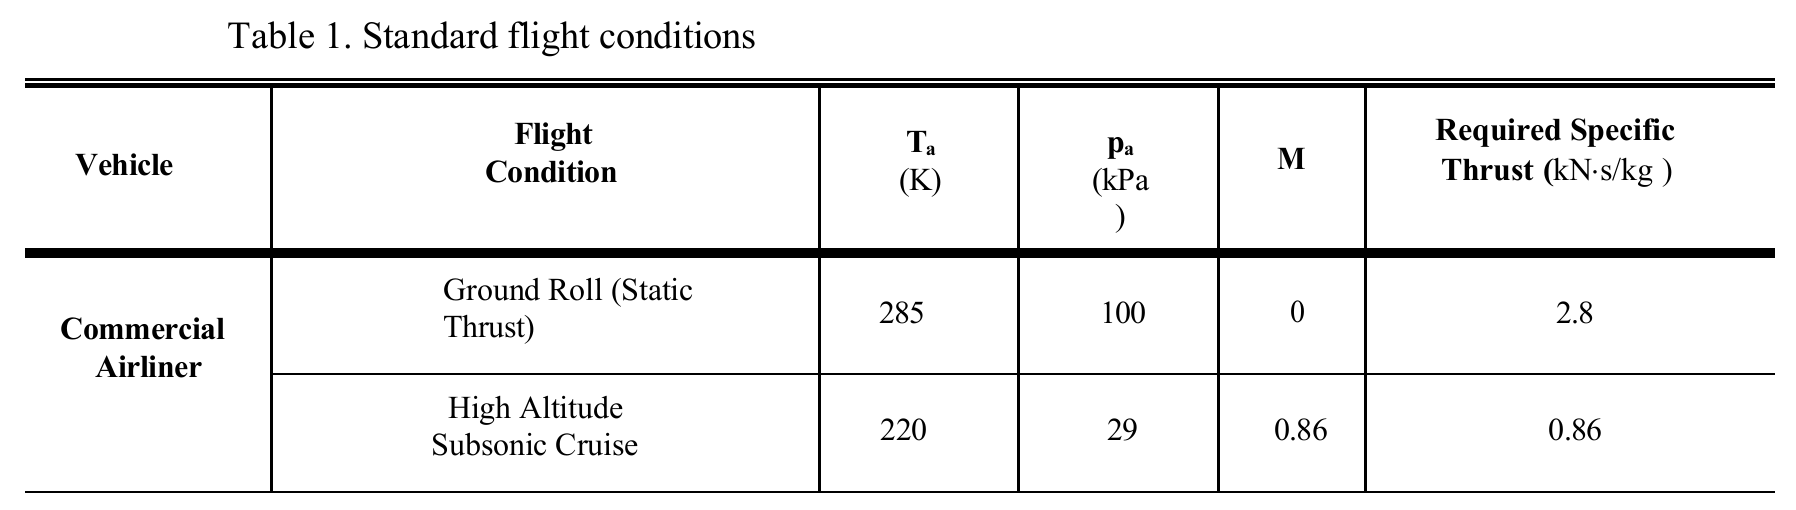

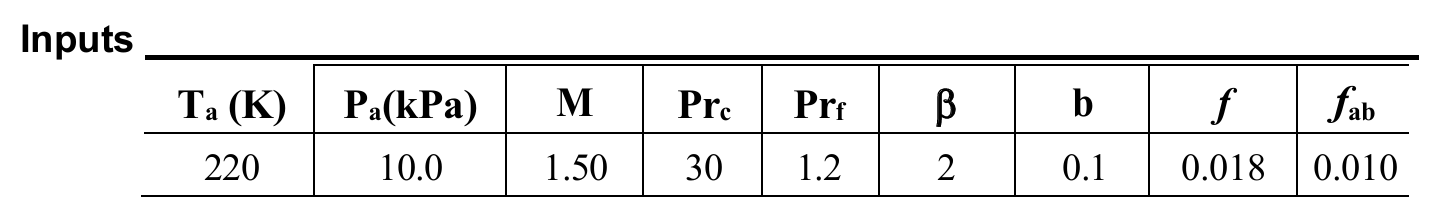


% GROUND ROLL
Ta_groundroll = 285;                    % K
Pa_groundroll = 100;                    % kPa
M_groundroll = 0;                       % dimensionless
SpecificThrust_groundroll = 2.8;        % kN-s/kg

% HIGH ALTITUDE SUBSONIC CRUISE
Ta_hasc = 220;                          % K
Pa_hasc = 29;                           % kPa
M_hasc = 0.86;                          % dimensionless
SpecificThrust_hasc = 0.86;             % kN-s/kg

Ta_inputs = [Ta_groundroll Ta_hasc];
Pa_inputs = [Pa_groundroll Pa_hasc];
M_inputs = [M_groundroll M_hasc];
ST = [SpecificThrust_groundroll SpecificThrust_hasc];

for i = 1:length(Ta_inputs)
    Ta = Ta_inputs(i);
    pa = Pa_inputs(i);
    M = M_inputs(i);


At least one END is missing. The statement beginning here does not have a matching end.

**TEST CASE INPUTS**

% 
% % % Ambient / flight
% Ta = 220;            % K
% pa = 10.0;           % kPa
% M  = 1.50;           % flight Mach

% Design/engine parameters (test case line)
% Prc = 30;            % compressor stagnation pressure ratio
% Prf = 1.2;           % fan stagnation pressure ratio
% bypass = 2.0;        % bypass ratio (b)
% b  = 0.1;            % bleed fraction (b)
% f = 0.05;            % fuel-air ratio main burner


**ACTUAL INPUTS**


Prc = 25;             % compressor stagnation pressure ratio
Prf = 0;              % fan stagnation pressure ratio
bypass = 0;           % bypass ratio (b)
b  = 0.05;            % bleed fraction (b)

% fuel-air ratio main burner
if i == 1;            % ground roll
    f = 0.03;            
    f_ab = 0.03;
else %i == 2;          % high altitude cruise
    f = 0.015;
    f_ab = 0.02;
end


**INLET / COMPRESSOR**


[P02,T02] = diffuser(Ta, pa, M);
fprintf('Diffuser exit temperature, T_02     = %.2f K\n', T02);
fprintf('Diffuser exit pressure, p_02        = %.2f kPa\n', P02);

[P03,T03,w3,Cpc] =compressor(P02,T02,Prc);
fprintf('Compressor exit temperature, T_03   = %.2f K\n', T03);
fprintf('Compressor exit pressure, p_03      = %.2f kPa\n', P03);

p03 = P03;
wc = w3/1000;


**COMBUSTOR**

 
% T03 = 956.9;

Diffuser exit temperature, T_02     = 285.00 K


Diffuser exit pressure, p_02        = 100.00 kPa


Compressor exit temperature, T_03   = 752.30 K


Compressor exit pressure, p_03      = 2500.00 kPa


% p03 = 1175;

[T04, p04, fmax,R,Cp4] = combustor(f, T03, p03,Cpc);

fprintf('Combustor exit temperature, T_04   = %.2f K\n', T04);
fprintf('Combustor exit pressure, p_04      = %.2f kPa\n', p04);
fprintf('fmax                               = %.2f \n', fmax);

T_04 = T04;
p_04 = p04;


**TURBINE AND AFTERBURNER**


% Test Case Values
% T_04 = 1689;        % K, stagnation temp at turbine inlet (burner ouput)

Combustor exit temperature, T_04   = 1852.18 K


Combustor exit pressure, p_04      = 2450.00 kPa


fmax                               = 0.03 


% p_04 = 1151;        % kPa, stagnation pressure at turbine inlet (burner ouput)
% wc = 648.8;        % kJ/kg of compressor
% ----------------------------------------------------------------------------

% Call turbine function (includes afterburner)
[T_06, p_06, wt, T_05, p_05] = turbine_and_afterburner(T_04, p_04, b, wc, f, f_ab);
  
% Display results
fprintf('Turbine exit temperature, T_05   = %.2f K\n', T_05);
fprintf('Turbine exit pressure, p_05      = %.2f kPa\n', p_05);
fprintf('Turbine shaft work, wt           = %.2f kJ/kg\n', wt);

fprintf('AB exit temperature, T_06        = %.2f K\n', T_06);
fprintf('AB exit pressure, p_06           = %.2f kPa\n', p_06);


**NOZZLE**


% % Ambient / flight
% Ta = 220;            % K
% pa = 10.0;           % kPa

Temperature is fine, appropriate bleed system


Turbine exit temperature, T_05   = 1409.22 K


Turbine exit pressure, p_05      = 749.89 kPa


Turbine shaft work, wt           = 474.15 kJ/kg


AB exit temperature, T_06        = 2460.07 K


AB exit pressure, p_06           = 749.89 kPa


% M  = 1.50;           % flight Mach

% T_05 = 1081;    % from turbine
% p_05 = 163.2;   % from turbine  
% p_a = 10.0;     % ambient pressure
% T_a = 220;      % ambient temperature
% M = 1.5;        % flight Mach number
% f = 0.018;      % fuel-air ratio from combustor


% Call nozzle function
[u_e, T_e, p_e, thrust_specific, TSFC] = core_nozzle(T_06, p_06, p_a, T_a, M, f, f_ab);

TSFC_final = TSFC*1000; 
thrust_specific_final = thrust_specific / 1000; 

% Display results
fprintf('Nozzle exit velocity, u_e       = %.2f m/s\n', u_e);
fprintf('Nozzle exit temperature, T_e    = %.2f K\n', T_e);
fprintf('Nozzle exit pressure, p_e       = %.2f kPa\n', p_e);
fprintf('Specific thrust                 = %.2f kN*s/kg\n', thrust_specific_final);
fprintf('TSFC                            = %.6f kg/(kN*s)\n', TSFC_final);

Unrecognized function or variable 'p_a'.